% files = {'chirp.mat'
%         'gong.mat'
%         'handel.mat'
%         'laughter.mat'
%         'splat.mat'
%         'train.mat'};


% S = zeros(10000,6);
% for i = 1:6
%     test     = load(files{i});
%     y        = test.y(1:10000,1);
%     S(:,i)   = y;
% end


% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA
% files = {'../input-data/matlab/z_chisq_seeds501982z_3085chi.mat'
%         '../input-data/matlab/zg_chisq_seeds501982z_3085chi.mat'
%         '../input-data/matlab/zng_chisq_seeds501982z_3085chi.mat'};
files = {'../input-data/matlab/zg_chisq_seeds501982z_3085chi.mat'
        '../input-data/matlab/zng_chisq_seeds501982z_3085chi.mat'};

n = 2;
Z = zeros(4194304, n);
for i = 1:n
    test     = load(files{i});
    y        = test.y(1, :)'; % The apostrophe denotes transpose.
    Z(:,i)   = y;
end
% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA

%% 

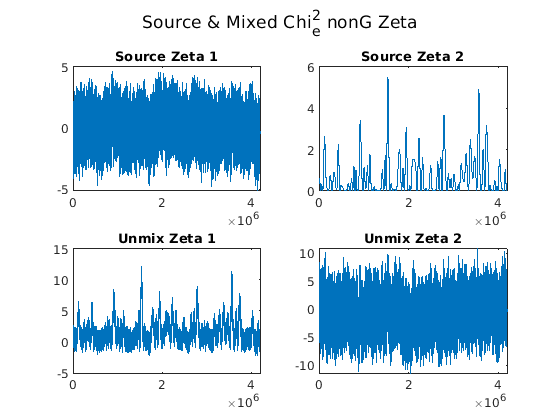


rng default % For reproducibility

% mixdata = S*randn(6) + randn(1,6);

% figure
% for i = 1:6
%     subplot(2,6,i)
%     plot(S(:,i))
%     title(['Sound ',num2str(i)])
%     subplot(2,6,i+6)
%     plot(mixdata(:,i))
%     title(['Mix ',num2str(i)])
% end


% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA
mixzeta = Z*randn(n) + randn(1,n);

figure
figtitle = sgtitle('Source & Mixed Chi^2_e nonG Zeta');
for i = 1:n
    subplot(2,n,i)
    plot(Z(:,i))
    title(['Source Zeta ',num2str(i)])
    subplot(2,n,i+n)
    plot(mixzeta(:,i))
    title(['Unmix Zeta ',num2str(i)])
end

% saveas(gcf,'figs/plt-src_and_mix-chisq_zng.png')
exportgraphics(gcf,'figs/plt-src_and_mix-chisq_zng.png')


% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA

%% 

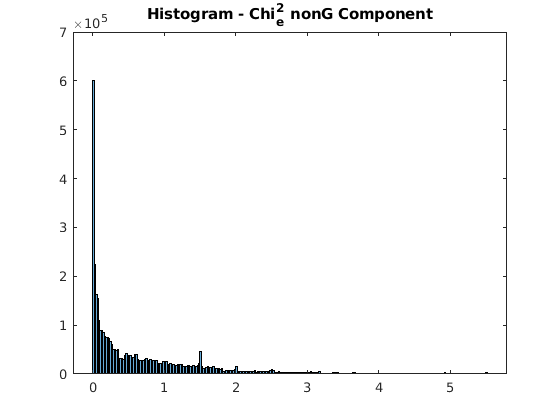


% mixdata = prewhiten(mixdata);
% figure
% histogram(S(:,1))


% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA
mixzeta = prewhiten(mixzeta);

figure
histogram(Z(:,2))
title('Histogram - Chi^2_e nonG Component')

exportgraphics(gcf,'figs/hist-chisq_ng.png')

% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA

%% 


% q = 6;
% Mdl = rica(mixdata,q,'NonGaussianityIndicator',ones(6,1));
% unmixed = transform(Mdl,mixdata);


% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA
q = n;
Model = rica(mixzeta,q, 'VerbosityLevel', 1, 'GradientTolerance',1e-7, 'StepTolerance',1e-6);


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  4.810159e+06 |   5.868e+06 |   0.000e+00 |        |   3.220e-07 |   0.000e+00 |   YES  |
|        1 |  4.727656e+06 |   5.679e+06 |   3.033e-01 |    OK  |   2.215e-08 |   1.250e-01 |   YES  |
|        2 |  4.262597e+06 |   8.898e+05 |   1.251e-01 |    OK  |   2.357e-08 |   1.000e+00 |   YES  |
|        3 |  4.249481e+06 |   1.504e+05 |   2.956e-02 |    OK  |   2.252e-08 |   1.000e+00 |   YES  |
|        4 |  4.249079e+06 |   5.182e+03 |   4.461e-03 |    OK  |   2.236e-08 |   1.000e+00 |   YES  |
|        5 |  4.249078e+06 |   4.686e+03 |   1.684e-04 |    OK  |   2.235e-08 |   1.000e+00 |   YES  

Model = rica(mixzeta,q, 'VerbosityLevel', 1, 'InitialTransformWeights',Model.TransformWeights, 'GradientTolerance',1e-10, 'StepTolerance',1e-10);


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  4.159838e+06 |   9.552e-02 |   0.000e+00 |        |   6.237e+00 |   0.000e+00 |   YES  |
|        1 |  4.159838e+06 |   1.775e-01 |   1.086e-08 |    OK  |   2.959e-08 |   1.490e-08 |   YES  |
|        2 |  4.159838e+06 |   1.549e-01 |   9.801e-10 |    OK  |   2.956e-08 |   6.985e-10 |   YES  |
|        3 |  4.159838e+06 |   1.194e-01 |   1.702e-09 |    OK  |   2.959e-08 |   2.500e-01 |   YES  |
|        4 |  4.159838e+06 |   1.194e-01 |   1.620e-15 |    NO  |   6.237e+00 |   8.882e-16 |    NO  |

         Infinity norm of the final gradient = 1.194e-01
              Two norm of the final step   

unmixedzeta = transform(Model, mixzeta);
% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA

%% 

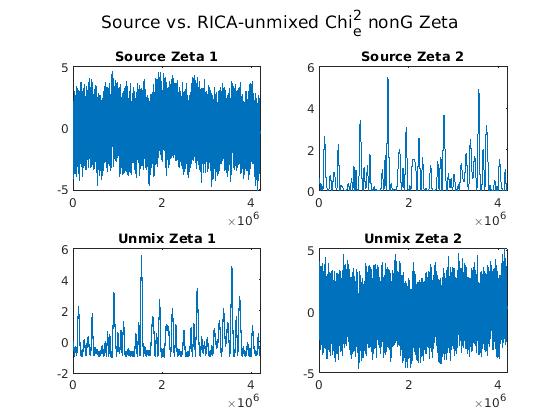


% figure
% for i = 1:6
%     subplot(2,6,i)
%     plot(S(:,i))
%     title(['Sound ',num2str(i)])
%     subplot(2,6,i+6)
%     plot(unmixed(:,i))
%     title(['Unmix ',num2str(i)])
% end


% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA
figure
for i = 1:n
    subplot(2,n,i)
    plot(Z(:, i))
    title(['Source Zeta ',num2str(i)])
    subplot(2,n,i+n)
    plot(unmixedzeta(:,i))
    title(['Unmix Zeta ',num2str(i)])
end
sgtitle('Source vs. RICA-unmixed Chi^2_e nonG Zeta')

% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA

%% 

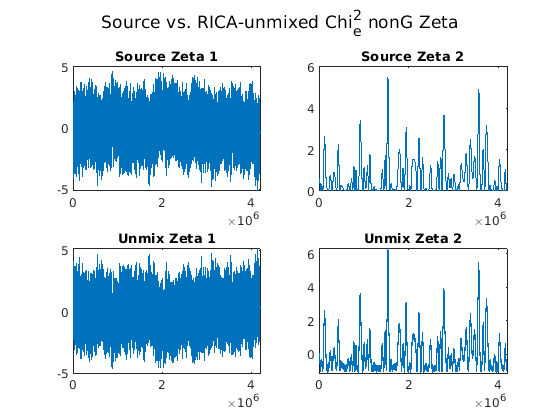


% unmixed = unmixed(:,[2,5,4,6,3,1]);
% for i = 1:6
%     unmixed(:,i) = unmixed(:,i)/norm(unmixed(:,i))*norm(S(:,i));
% end

% figure
% for i = 1:6
%     subplot(2,6,i)
%     plot(S(:,i))
%     ylim([-1,1])
%     title(['Sound ',num2str(i)])
%     subplot(2,6,i+6)
%     plot(unmixed(:,i))
%     ylim([-1,1])
%     title(['Unmix ',num2str(i)])
% end


% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA 
unmixedzeta = unmixedzeta(:,[2,1]);
for i = 1:2
    unmixedzeta(:,i) = unmixedzeta(:,i)/norm(unmixedzeta(:,i))*norm(Z(:,i));
end

figure
sgtitle('Source vs. RICA-unmixed Chi^2_e nonG Zeta')
for i = 1:n
    subplot(2,n,i)
    plot(Z(:,i))
    % ylim([-5,5])
    title(['Source Zeta ',num2str(i)])
    subplot(2,n,i+n)
    plot(unmixedzeta(:,i))
    % ylim([-5,5])
    title(['Unmix Zeta ',num2str(i)])
end

exportgraphics(gcf,'figs/plt-unmix-src_vs_rica-chisq_zng.png')

% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA


%% 

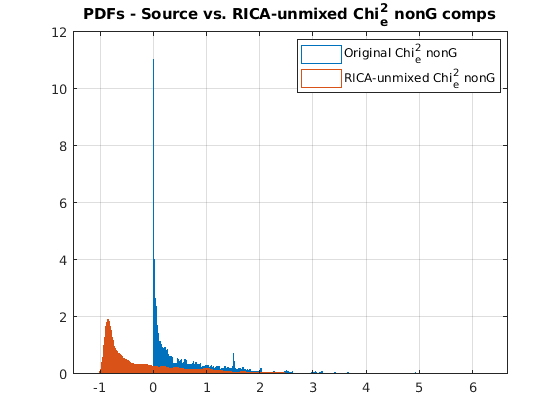

% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA
sourceng = Z(:, 2);
ricang = unmixedzeta(:, 2);
% minsource = min(cdfsource); maxsource = max(cdfsource);
% minrica = min(cdfrica); maxrica = max(cdfrica);

% tmp = [cdfsource, cdfrica];
% tmpmax = max(tmp(:)); tmpmin = min(tmp(:));
% x = -2:.1:8;
% x = linspace(tmpmin, tmpmax);

numbins = 600;

% PLOT PDF comparison
figure
histogram(sourceng, numbins, 'Normalization','pdf', 'FaceColor','none', 'EdgeColor','auto'); hold on;
histogram(ricang, numbins, 'Normalization','pdf', 'FaceColor','none', 'EdgeColor','auto');
grid on;
title('PDFs - Source vs. RICA-unmixed Chi^2_e nonG comps')
legend('Original Chi_e^2 nonG', 'RICA-unmixed Chi_e^2 nonG', 'Location', 'best');
hold off;

exportgraphics(gcf,'figs/pdf-chisq_ng.png')

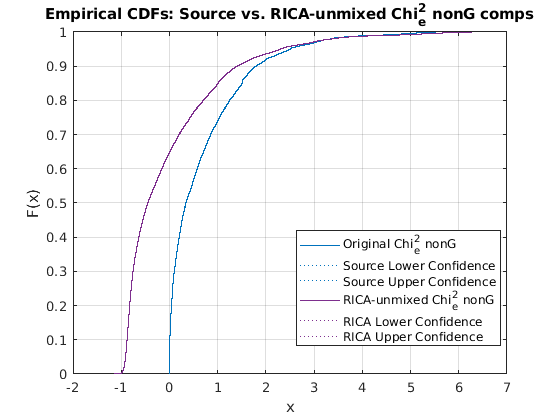


% PLOT CDF comparison
figure
ecdf(sourceng, 'Bounds', 'on', 'Alpha', 0.3); hold on;
ecdf(ricang, 'Bounds', 'on', 'Alpha', 0.3);
grid on;
title('Empirical CDFs: Source vs. RICA-unmixed Chi^2_e nonG comps')
legend('Original Chi_e^2 nonG', 'Source Lower Confidence','Source Upper Confidence', 'RICA-unmixed Chi_e^2 nonG', 'RICA Lower Confidence', 'RICA Upper Confidence', 'Location', 'best');
hold off;

exportgraphics(gcf,'figs/ecdf-src_vs_rica-chisq_zng.png')


[h,p,k] = kstest2(Z(:, 2),unmixedzeta(:, 2),'Alpha',0.05);
% ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA % ZETA


%%


function Z = prewhiten(X)
% X = N-by-P matrix for N observations and P predictors
% Z = N-by-P prewhitened matrix

    % 1. Size of X.
    [N,P] = size(X);
    assert(N >= P);

    % 2. SVD of covariance of X. We could also use svd(X) to proceed but N
    % can be large and so we sacrifice some accuracy for speed.
    [U,Sig] = svd(cov(X));
    Sig     = diag(Sig);
    Sig     = Sig(:)';

    % 3. Figure out which values of Sig are non-zero.
    tol = eps(class(X));
    idx = (Sig > max(Sig)*tol);
    assert(~all(idx == 0));

    % 4. Get the non-zero elements of Sig and corresponding columns of U.
    Sig = Sig(idx);
    U   = U(:,idx);

    % 5. Compute prewhitened data.
    mu = mean(X,1);
    Z = bsxfun(@minus,X,mu);
    Z = bsxfun(@times,Z*U,1./sqrt(Sig));
end